# Identification of model constants

## omega nonlinearity identification

## positive ramp

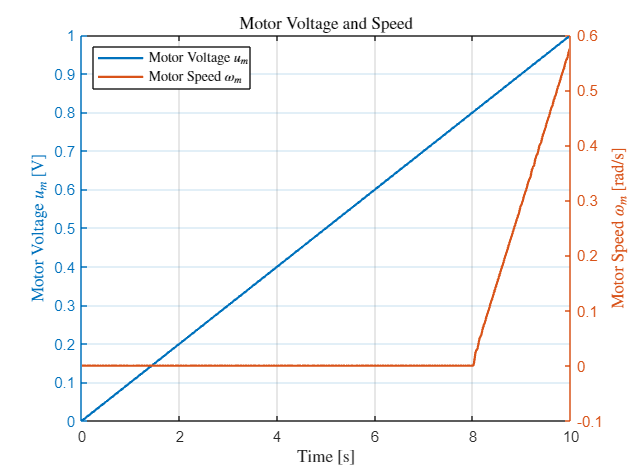


load("Deadzone_ramp_1v.mat");  % Load the timeseries

% Extract data
u_m = Um_Wm.Data(:,1);        % Motor voltage
omega_m = Um_Wm.Data(:,2);    % Motor speed
time = Um_Wm.Time;            % Time vector

% Create figure
figure;
yyaxis left
plot(time, u_m, 'LineWidth', 1.5);
ylabel('Motor Voltage $u_m$ [V]', 'Interpreter', 'latex');

yyaxis right
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Motor Speed $\omega_m$ [rad/s]', 'Interpreter', 'latex');

xlabel('Time [s]', 'Interpreter', 'latex');
title('Motor Voltage and Speed', 'Interpreter', 'latex');
grid on;

% Place legend in the top-left
legend({'Motor Voltage $u_m$', 'Motor Speed $\omega_m$'}, ...
    'Location', 'northwest', 'Interpreter', 'latex');

## negative ramp

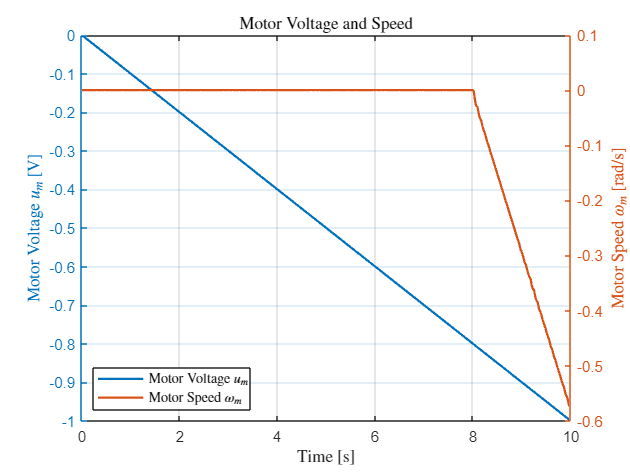

load("Deadzone_ramp_minus1v.mat");  % Load the timeseries

% Extract data
u_m = Um_Wm.Data(:,1);        % Motor voltage
omega_m = Um_Wm.Data(:,2);    % Motor speed
time = Um_Wm.Time;            % Time vector

% Create figure
figure;
yyaxis left
plot(time, u_m, 'LineWidth', 1.5);
ylabel('Motor Voltage $u_m$ [V]', 'Interpreter', 'latex');

yyaxis right
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Motor Speed $\omega_m$ [rad/s]', 'Interpreter', 'latex');

xlabel('Time [s]', 'Interpreter', 'latex');
title('Motor Voltage and Speed', 'Interpreter', 'latex');
grid on;

% Place legend in the bottom-left
legend({'Motor Voltage $u_m$', 'Motor Speed $\omega_m$'}, ...
    'Location', 'southwest', 'Interpreter', 'latex');

## Um saturation identification

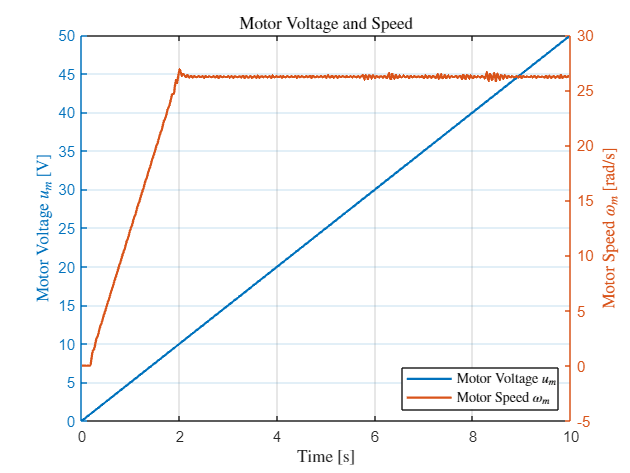

clc;
clear;

% Load the data
load("motor_saturation_plus.mat");

% Extract data from timeseries
u_m = Um_Wm.Data(:,1);        % Motor voltage
omega_m = Um_Wm.Data(:,2);    % Motor speed
time = Um_Wm.Time;            % Time vector

% Create figure
figure;
yyaxis left
plot(time, u_m, 'LineWidth', 1.5);
ylabel('Motor Voltage $u_m$ [V]', 'Interpreter', 'latex');

yyaxis right
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Motor Speed $\omega_m$ [rad/s]', 'Interpreter', 'latex');

xlabel('Time [s]', 'Interpreter', 'latex');
title('Motor Voltage and Speed', 'Interpreter', 'latex');
grid on;

legend({'Motor Voltage $u_m$', 'Motor Speed $\omega_m$'}, ...
    'Location', 'southeast', 'Interpreter', 'latex');

## motot resistance identification

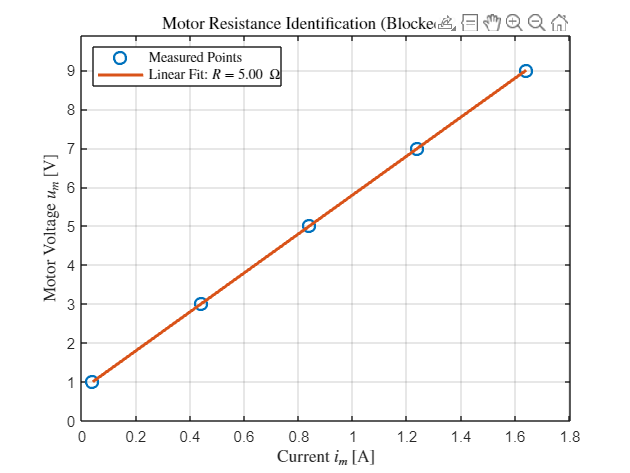


clc;
clear;

% Folder containing data files
folder = 'Data';

% Data files and corresponding motor voltages
files = {'Im_Umstep_1V.mat', 'Im_Umstep_3V.mat', 'Im_Umstep_5V.mat', 'Im_Umstep_7V.mat', 'Im_Umstep_9V.mat'};
voltages = [1, 3, 5, 7, 9];  % [V]
currents = zeros(size(voltages));  % Preallocate array for steady-state currents

% Extract Steady-State Currents from Timeseries
for k = 1:length(files)
    load(fullfile(folder, files{k}), 'Im');  % Load only the 'Im' variable

    % Use data after 2.5 seconds for steady-state analysis
    idx = Im.Time > 2.5;
    steady_current = mean(Im.Data(idx));

    currents(k) = steady_current;
end

% Calculate Pointwise Resistances (Optional – for reference)
resistances = voltages ./ currents;

% Estimate Global Resistance Using Least Squares Fit (with offset)
R_fit = polyfit(currents, voltages, 1);     % Fit: voltage = R * current + offset
R_estimated = R_fit(1);                     % Slope = resistance
offset = R_fit(2);                          % Intercept
fitted_voltage = polyval(R_fit, currents);  % Compute fitted values

% Plot the Results
figure;
plot(currents, voltages, 'o', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'Measured Points');
hold on;
plot(currents, fitted_voltage, '-', 'LineWidth', 2, ...
    'DisplayName', sprintf('Linear Fit: $R = %.2f\\ \\Omega$', R_estimated));
grid on;
xlabel('Current $i_m$ [A]', 'Interpreter', 'latex');
ylabel('Motor Voltage $u_m$ [V]', 'Interpreter', 'latex');
title('Motor Resistance Identification (Blocked Rotor)', 'Interpreter', 'latex');
legend('Location', 'northwest', 'Interpreter', 'latex');

% Set axes to start from 0 with some margin
xlim([0, max(currents)*1.1]);
ylim([0, max(voltages)*1.1]);

## motor inductance identification

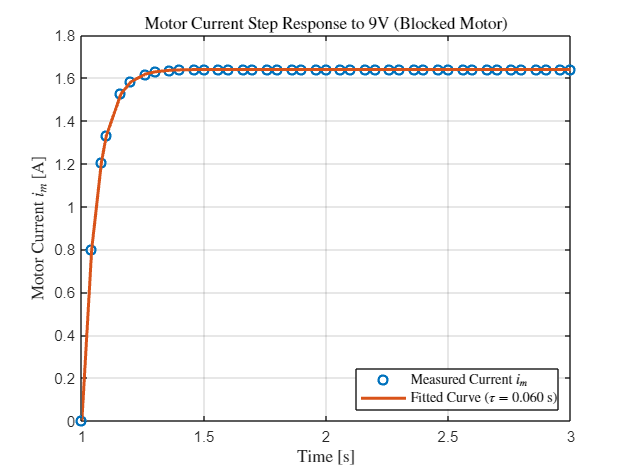

% Load and Prepare Data
clc;
clear;

% Load the timeseries
load('Data\Im_Umstep_9V.mat');

% Cut the timeseries to start from t = 1 second
Im_cut = getsampleusingtime(Im, 1, Im.Time(end));

% Extract vectors from timeseries
time = Im_cut.Time;
data = Im_cut.Data;

% Estimate Steady-State Value
% Use last 10 samples to estimate steady state
y_inf = mean(data(end-10:end));

% Transform Data for Exponential Fitting
% We fit (y_inf - data) = A * exp(-t / tau)
transformed_data = y_inf - data;

% Fit a simple exponential to the transformed data
f = fit(time, transformed_data, 'exp1');  % f(x) = a * exp(b*x)

% Extract fitted parameters
a = f.a;  % Amplitude
b = f.b;  % Exponent

% Calculate time constant tau
tau = -1 / b;

% Reconstruct the fitted response
fitted_data = y_inf - f(time);  % Reversing the transformation

% Plot Results
figure;
plot(time, data, 'o', 'MarkerSize', 6, 'DisplayName', 'Measured Current $i_m$', 'LineWidth', 1.5); 
hold on;
plot(time, fitted_data, '-', 'LineWidth', 2, 'DisplayName', sprintf('Fitted Curve ($\\tau = %.3f$ s)', tau));
grid on;
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Motor Current $i_m$ [A]', 'Interpreter', 'latex');
title('Motor Current Step Response to 9V (Blocked Motor)', 'Interpreter', 'latex');
legend('Location', 'southeast', 'Interpreter', 'latex');

## motor electromechanical constant identification

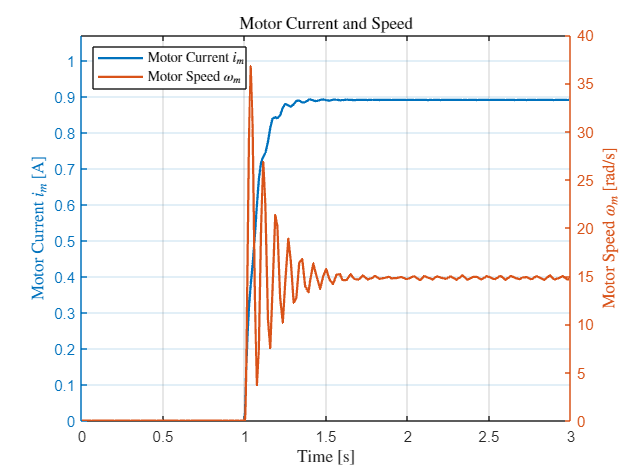

load('constantOmega_Um6v.mat');  % Load the timeseries

% Extract data from timeseries
data = ans.Data;
time = ans.Time;

i_m = data(:,1);       % First column = motor current [A]
omega_m = data(:,2);   % Second column = motor speed [rad/s]

% Create figure
figure;

yyaxis left
plot(time, i_m, 'LineWidth', 1.5);
ylabel('Motor Current $i_m$ [A]', 'Interpreter', 'latex');

% Add headroom to current axis
current_min = min(i_m);
current_max = max(i_m);
ylim([current_min, current_max * 1.2]);  % 20% headroom above

yyaxis right
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Motor Speed $\omega_m$ [rad/s]', 'Interpreter', 'latex');

grid on;
xlabel('Time [s]', 'Interpreter', 'latex');
title('Motor Current and Speed', 'Interpreter', 'latex');
legend({'Motor Current $i_m$', 'Motor Speed $\omega_m$'}, 'Location', 'northwest', 'Interpreter', 'latex');

## generator resistance identification

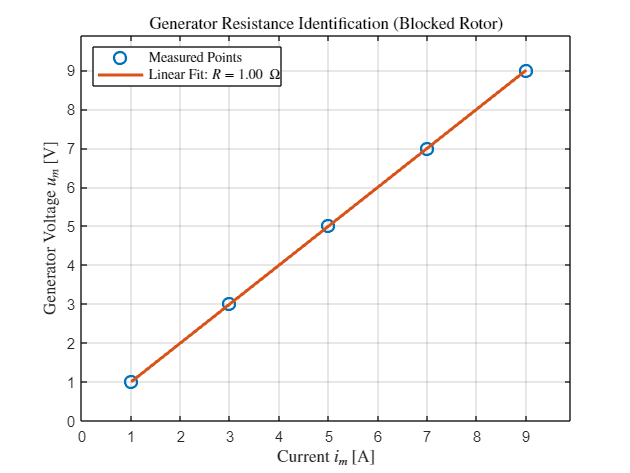


clc;
clear;

% Folder containing data files
folder = 'Data';

% Data files and corresponding motor voltages
files = {'Ug_step_1v', 'Ug_step_3v', 'Ug_step_5v', 'Ug_step_7v', 'Ug_step_9v'};
voltages = [1, 3, 5, 7, 9];  % [V]
currents = zeros(size(voltages));  % Preallocate array for steady-state currents

% Extract Steady-State Currents from Timeseries
for k = 1:length(files)
    load(fullfile(folder, files{k}), 'Ig');  % Load only the 'Im' variable

    % Use data after 2.5 seconds for steady-state analysis
    idx = Ig.Time > 2.5;
    steady_current = mean(Ig.Data(idx));

    currents(k) = steady_current;
end

% Calculate Pointwise Resistances (Optional – for reference)
resistances = voltages ./ currents;

% Estimate Global Resistance Using Least Squares Fit (with offset)
R_fit = polyfit(currents, voltages, 1);     % Fit: voltage = R * current + offset
R_estimated = R_fit(1);                     % Slope = resistance
offset = R_fit(2);                          % Intercept
fitted_voltage = polyval(R_fit, currents);  % Compute fitted values

% Plot the Results
figure;
plot(currents, voltages, 'o', 'MarkerSize', 8, 'LineWidth', 1.5, ...
    'DisplayName', 'Measured Points');
hold on;
plot(currents, fitted_voltage, '-', 'LineWidth', 2, ...
    'DisplayName', sprintf('Linear Fit: $R = %.2f\\ \\Omega$', R_estimated));
grid on;
xlabel('Current $i_m$ [A]', 'Interpreter', 'latex');
ylabel('Generator Voltage $u_m$ [V]', 'Interpreter', 'latex');
title('Generator Resistance Identification (Blocked Rotor)', 'Interpreter', 'latex');
legend('Location', 'northwest', 'Interpreter', 'latex');

% Set axes to start from 0 with some margin
xlim([0, max(currents)*1.1]);
ylim([0, max(voltages)*1.1]);

## generator inductance identification

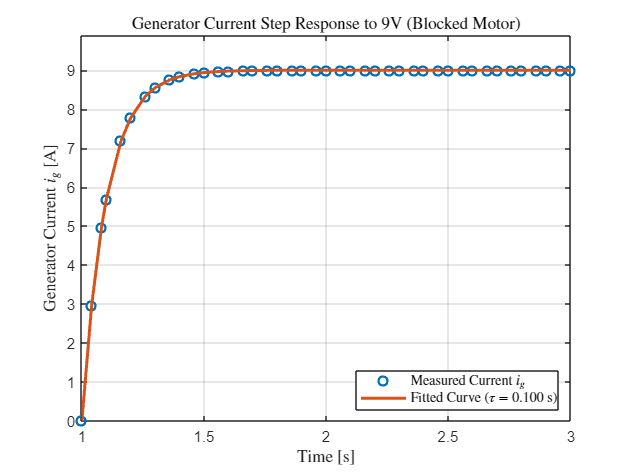

% Load and Prepare Data
clc;
clear;

% Load the timeseries
load('Data\Ug_step_9v.mat');

% Cut the timeseries to start from t = 1 second
Ig_cut = getsampleusingtime(Ig, 1, Ig.Time(end));

% Extract vectors from timeseries
time = Ig_cut.Time;
data = Ig_cut.Data;

% Estimate Steady-State Value
% Use last 10 samples to estimate steady state
y_inf = mean(data(end-10:end));

% Transform Data for Exponential Fitting
% We fit (y_inf - data) = A * exp(-t / tau)
transformed_data = y_inf - data;

% Fit a simple exponential to the transformed data
f = fit(time, transformed_data, 'exp1');  % f(x) = a * exp(b*x)

% Extract fitted parameters
a = f.a;  % Amplitude
b = f.b;  % Exponent

% Calculate time constant tau
tau = -1 / b;

% Reconstruct the fitted response
fitted_data = y_inf - f(time);  % Reversing the transformation

% Plot Results
figure;
plot(time, data, 'o', 'MarkerSize', 6, 'DisplayName', 'Measured Current $i_g$', 'LineWidth', 1.5); 
hold on;
plot(time, fitted_data, '-', 'LineWidth', 2, 'DisplayName', sprintf('Fitted Curve ($\\tau = %.3f$ s)', tau));
grid on;
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Generator Current $i_g$ [A]', 'Interpreter', 'latex');
title('Generator Current Step Response to 9V (Blocked Motor)', 'Interpreter', 'latex');
legend('Location', 'southeast', 'Interpreter', 'latex');

% Only extend Y-axis
ylim([0, max(data)*1.1]);

## generetor Ke identification

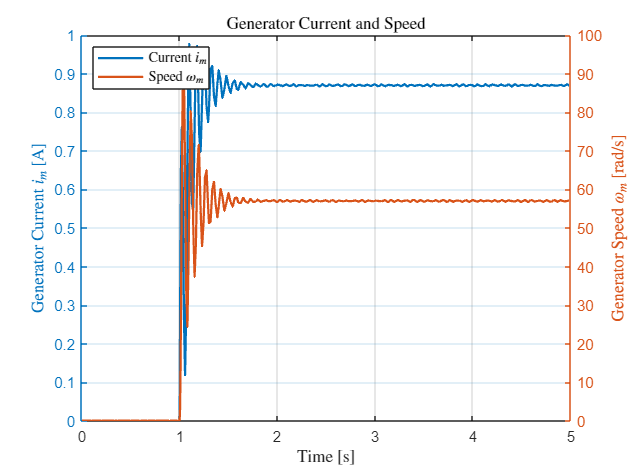

load('Ug_step_6v.mat');  % Load the timeseries

% Assuming 'ans' is the timeseries you want to plot
data = ans.Data;       % Extract data from timeseries
time = ans.Time;       % Extract time vector

i_m = data(:,1);       % First column = motor current [A]
omega_m = data(:,2);   % Second column = motor speed [rad/s]

% Create figure
figure;

yyaxis left
plot(time, i_m, 'LineWidth', 1.5);
ylabel('Generator Current $i_m$ [A]', 'Interpreter', 'latex');

yyaxis right
plot(time, omega_m, 'LineWidth', 1.5);
ylabel('Generator Speed $\omega_m$ [rad/s]', 'Interpreter', 'latex');

grid on;
xlabel('Time [s]', 'Interpreter', 'latex');
title('Generator Current and Speed', 'Interpreter', 'latex');
legend({'Current $i_m$', 'Speed $\omega_m$'}, 'Location', 'northwest', 'Interpreter', 'latex');

## vita je dement

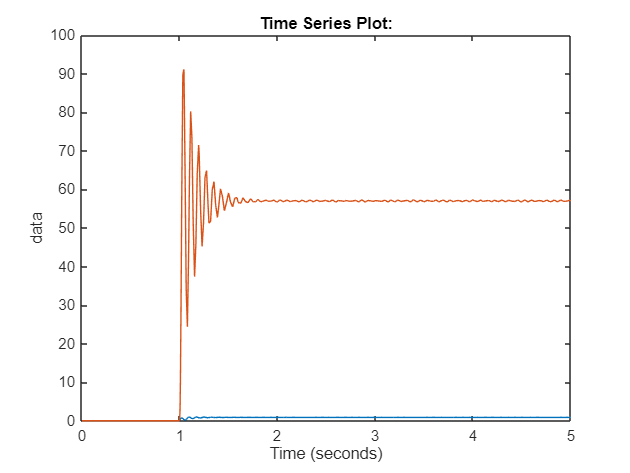

data = load('Ug_step_6v.mat');
plot(data.ans);